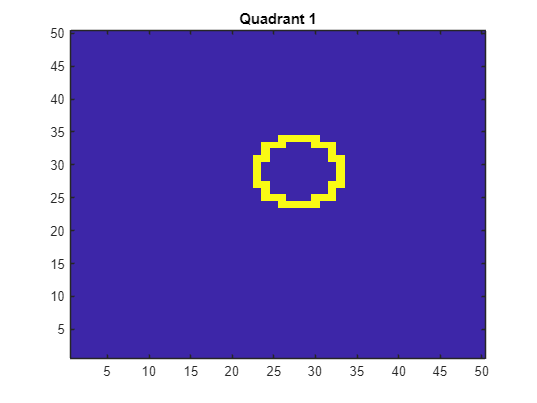

% Autor: Luis Eduardo Arenas Deseano
% Proyecto: Sistemas Inteligentes
% Descripción: Comparacion de Imagenes con KErnel de SVM
% Fecha: 1/12/2024

d = 50;  % Height and width of the images in pixels
n = 5e4; % Sample size

X = zeros(n,d^2); % Predictor matrix preallocation 
Y = zeros(n,1);   % Label preallocation
theta = 0:(1/d):(2*pi);
r = 5;            % Circle radius
rng(1);           % For reproducibility

for j = 1:n
    figmat = zeros(d);                       % Empty image
    c = datasample((r + 1):(d - r - 1),2);   % Random circle center
    x = r*cos(theta) + c(1);                 % Make the circle 
    y = r*sin(theta) + c(2);               
    idx = sub2ind([d d],round(y),round(x));  % Convert to linear indexing
    figmat(idx) = 1;                         % Draw the circle
    X(j,:) = figmat(:);                % Store the data
    Y(j) = (c(2) >= floor(d/2)) + 2*(c(2) < floor(d/2)) + ...
        (c(1) < floor(d/2)) + ...
        2*((c(1) >= floor(d/2)) & (c(2) < floor(d/2))); % Determine the quadrant
end

figure
imagesc(figmat)
h = gca;
h.YDir = 'normal';
title(sprintf('Quadrant %d',Y(end)))


p = 0.25;
CVP = cvpartition(Y,'Holdout',p); % Cross-validation data partition
isIdx = training(CVP);            % Training sample indices
oosIdx = test(CVP);               % Test sample indices

t = templateSVM('SaveSupportVectors',true);
MdlSV = fitcecoc(X(isIdx,:),Y(isIdx),'Learners',t);
isLoss = resubLoss(MdlSV)

isLoss = 0


infoMdlSV = whos('MdlSV');
mbMdlSV = infoMdlSV.bytes/1.049e6

mbMdlSV = 763.6163


Mdl = discardSupportVectors(MdlSV);
CMdl = compact(Mdl);
info = whos('Mdl','CMdl');
[bytesCMdl,bytesMdl] = info.bytes;
memReduction = 1 - [bytesMdl bytesCMdl]/infoMdlSV.bytes

memReduction =     0.0626    0.9996



clear Mdl MdlSV

oosLoss = loss(CMdl,X(oosIdx,:),Y(oosIdx))

oosLoss = 0

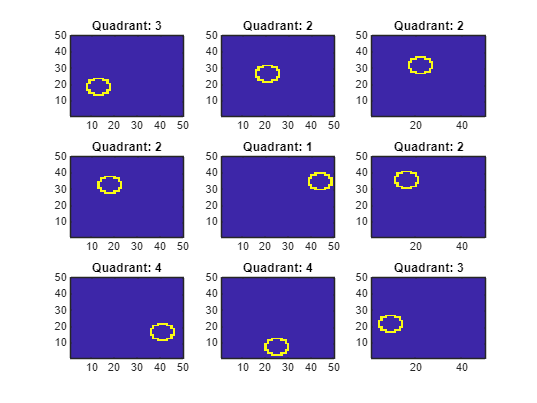


yHat = predict(CMdl,X(oosIdx,:));
nVec = 1:size(X,1);
oosIdx = nVec(oosIdx);

figure;
for j = 1:9
    subplot(3,3,j)
    imagesc(reshape(X(oosIdx(j),:),[d d]))
    h = gca;
    h.YDir = 'normal';
    title(sprintf('Quadrant: %d',yHat(j)))
end
text(-1.33*d,4.5*d + 1,'Predictions','FontSize',17)